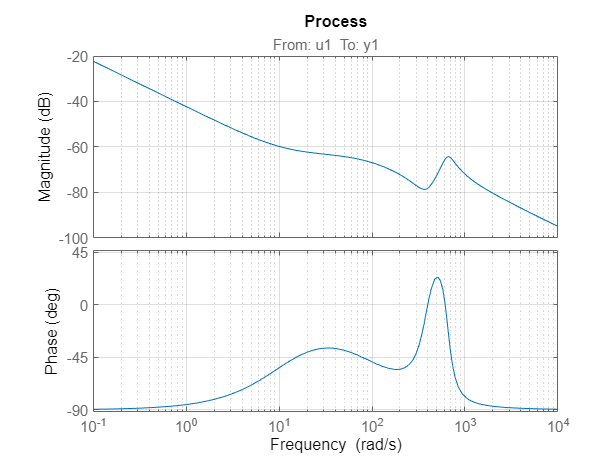

load modello_j1.mat

process = modello_continuo_tf_j1;


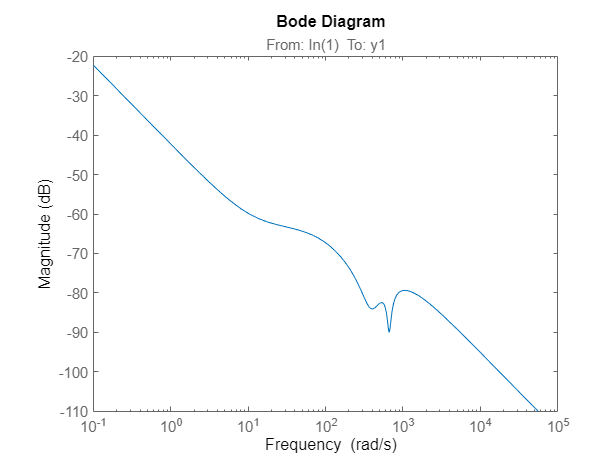

s=tf('s');
[gpeak,fpeak] = getPeakGain(process*10^(70/20),[],[300 1000]); % constraint of the frequencies personalize for our system
if(gpeak > 1/10)
    notch_filter=notch(fpeak,1/10/gpeak);
else
    notch_filter=1;
end
process_notch = process * notch_filter;


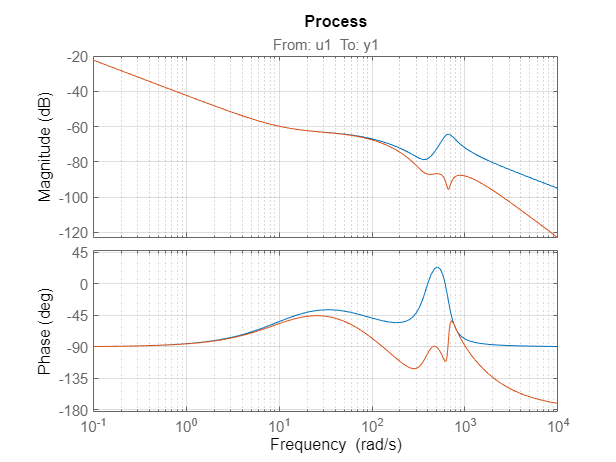

w_f=400;
filter = 1/(s/w_f+1)^1;



% ylim([-120 -40])
total_process = minreal(process_notch * filter);

tot_filter = filter * notch_filter;


Scelta dell'intervallo di frequenze d'interesse

w_inf = 1;
w_sup = 10^4;

internal_joint1.wc_des = 250;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x, 0, 0, 0, 0],total_process,internal_joint1.wc_des,0);

% Massima sensitività
internal_joint1.MS = 1.5;

% Reiezione disturbo di misura
internal_joint1.wh = 2000;
internal_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint1.wl = 10;
internal_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint1.PM_min = 65;
w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;internal_joint1.wl;internal_joint1.wh]));

nlcon = @(x)pid_filt_constraints([x, 0, 0, 0, 0], total_process, w_vector, ...
                                 internal_joint1.MS, internal_joint1.wh, internal_joint1.Fh_max, ...
                                 internal_joint1.wl, internal_joint1.Dl_max, internal_joint1.PM_min,0);

timeout = 60*2;
internal_joint1.aKp = [5800, 100, 10000];

x0 = [internal_joint1.aKp(1)];


problem = createOptimProblem('fmincon','x0',x0,  'objective',J, 'lb',[internal_joint1.aKp(2)],  'ub', [internal_joint1.aKp(3)],  'nonlcon',nlcon);

solver = GlobalSearch('MaxTime',timeout);
x = run(solver,problem);

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       27         876                                     876            1    Initial Point
     200     1248         876                                     876            1    Stage 1 Local
     273     1352         876          1386         1515          876            1    Stage 2 Local
     300     1379         876     1.852e+04         1663                              Stage 2 Search
     400     1479         876          1044         1044                              Stage 2 Search
     438     1542         876          1011         1051          876            1    Stage 2 Local
     500     1604         876     1.272e+04         1456                              Stage 2 Search
     542     1670         876          2067         2098          876            1    Stage 2 Loc

x = 6.3471e+03

ans =    -0.0132   -0.0998   -0.3337   -0.0000


ans = 1.1689

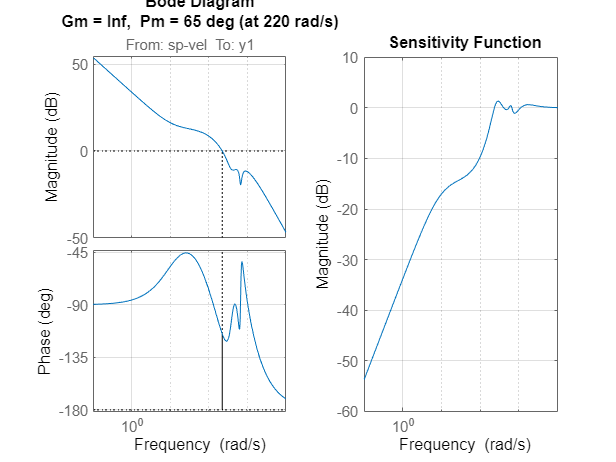


s=tf('s');
Kp = x(1);
Cv_joint1 = tf(Kp);
Cv_joint1.InputName = 'sp-vel';
Cv_joint1.OutputName = 'torque';

Loop_int_joint1 = total_process*Cv_joint1;





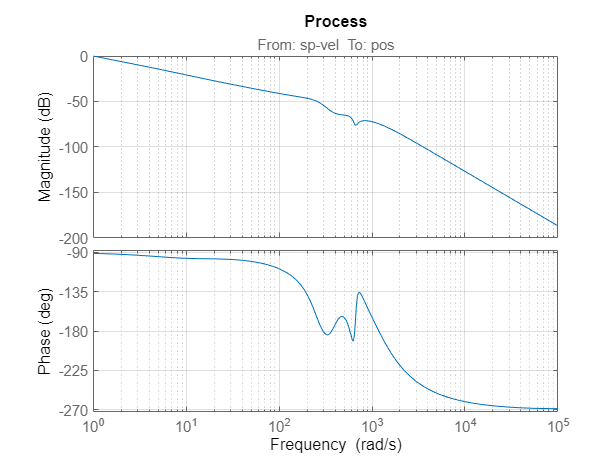

%% Extern loop
process_ext = minreal(feedback(Loop_int_joint1,1)*1/s);



external_joint1.wc_des = 200;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x(1), x(2), 0, 0, 0],process_ext,external_joint1.wc_des,0);
% Massima sensitività
external_joint1.MS = 1.5;

% Reiezione disturbo di misura
external_joint1.wh = 2000;
external_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint1.wl = 10;
external_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint1.PM_min = 75;

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;external_joint1.wl;external_joint1.wh]));

nlcon = @(x)pid_filt_constraints([x(1), x(2), 0, 0, 0], process_ext, w_vector, ...
                                 external_joint1.MS, external_joint1.wh, external_joint1.Fh_max, ...
                                 external_joint1.wl, external_joint1.Dl_max, external_joint1.PM_min,0);

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
external_joint1.aKp = [130, 0.01, 2000];
external_joint1.aKi = [1/200, 1/1000, 100];


x0 = [external_joint1.aKp(1), external_joint1.aKi(1)];

opt1=optimoptions("ga","MaxTime",3600*0.1,'InitialPopulation',x0);

x1=ga(J,2,[],[],[],[],[external_joint1.aKp(2), external_joint1.aKi(2)] ...
    ,[external_joint1.aKp(3), external_joint1.aKi(3)] ...
    ,nlcon,opt1);


Single objective optimization:
2 Variable(s)
4 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2524       14419.1    3.149e-06      0
    2           4986       14418.9    0.0001163      0
    3           7448       14550.6            0      0
    4           9851       14417.7    0.0009978      0
Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


ans =    -0.0964   -0.0891   -0.0648    0.0010


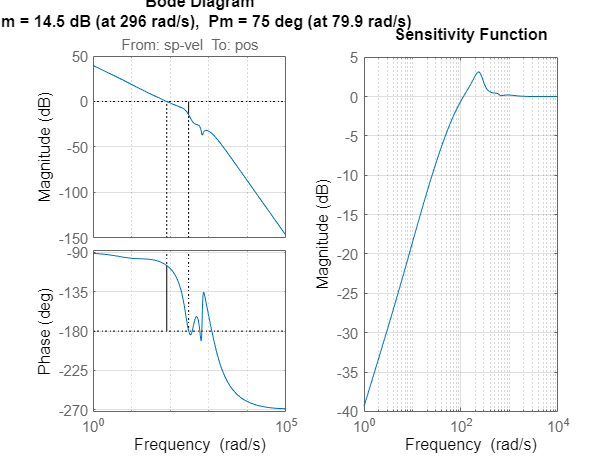

ans = 1.4352

s=tf('s');
Kp=x1(1); Ki=x1(2);
Cp_joint1=(Kp+Ki/s);

Loop_ext_joint1 = process_ext*Cp_joint1;





x = [x, 0, 0, 0, 0];
x1 = [x1, 0, 0, 0];
save("parameters_controller_int_joint1_" +num2str(w_f)+"_"+num2str(internal_joint1.PM_min)+".mat", "x")
save("parameters_controller_ext_joint1_"+num2str(w_f)+"_"+num2str(external_joint1.PM_min)+".mat","x1")
save("tot_filter_joint1_"+num2str(w_f)+"_"+num2str(external_joint1.PM_min)+".mat","tot_filter");